function xout = nhp(x,beta,delta,n) %Positions,beta,delta,#iterations
N=length(x);
xout=zeros(n,N);
dt=beta/N;
for i = 1:n
    k=randi(N);
    kplus=mod(k,N)+1; %adjusted for matlab indexing, ensuring if K = "N" K+ <- 1
    kminus=mod(k-2,N)+1; %adjusted for matlab indexing, ensuring if K = "0" K- <- "N-1"
    xdash=x(k)+(2*rand()-1)*delta;
    %prefactor of pfree cancels out when setting upsilon = pib/pia so have
    %removed from calculation, again setting m=h=1 for simplicity
    expa=(-(x(kminus)-x(k))^2 / (2*dt)) + (-(x(k)-x(kplus))^2 / (2*dt)) + (-0.5*dt*x(k)^2);
    expb=(-(x(kminus)-xdash)^2 / (2*dt)) + (-(xdash-x(kplus))^2 / (2*dt)) + (-0.5*dt*xdash^2);
    upsilon=exp(expb-expa);
    if rand() < upsilon
        x(k) = xdash;
    end
    xout(i,:)=x;
end
end

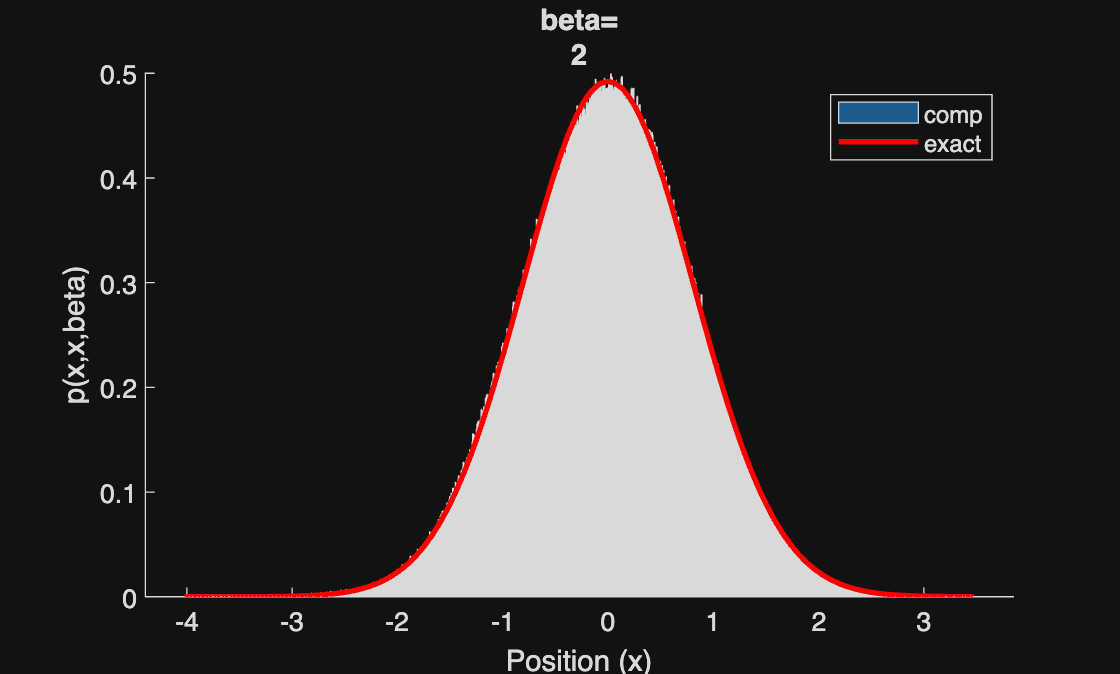

N=20;
xin=linspace(-1,1,N);
nsteps=10000000;
beta=2;
samples=nhp(xin,beta,0.5,nsteps);
burn=round(0.2*nsteps);
samples=samples(burn:nsteps,:);
samples=samples(:)';
xplot=linspace(min(samples),max(samples),100);
pexact=sqrt(tanh(beta/2)/pi)*exp(-xplot.^2*tanh(beta/2)); %diagonal density matrix of eq 6.24, normalized by dividing by Z(beta)
figure;
hold on;
histogram(samples,'Normalization','pdf');
plot(xplot,pexact,'r-','LineWidth',2);
xlabel('Position (x)');
ylabel('p(x,x,beta)');
legend('comp',"exact");
title(["beta=",num2str(beta)]);

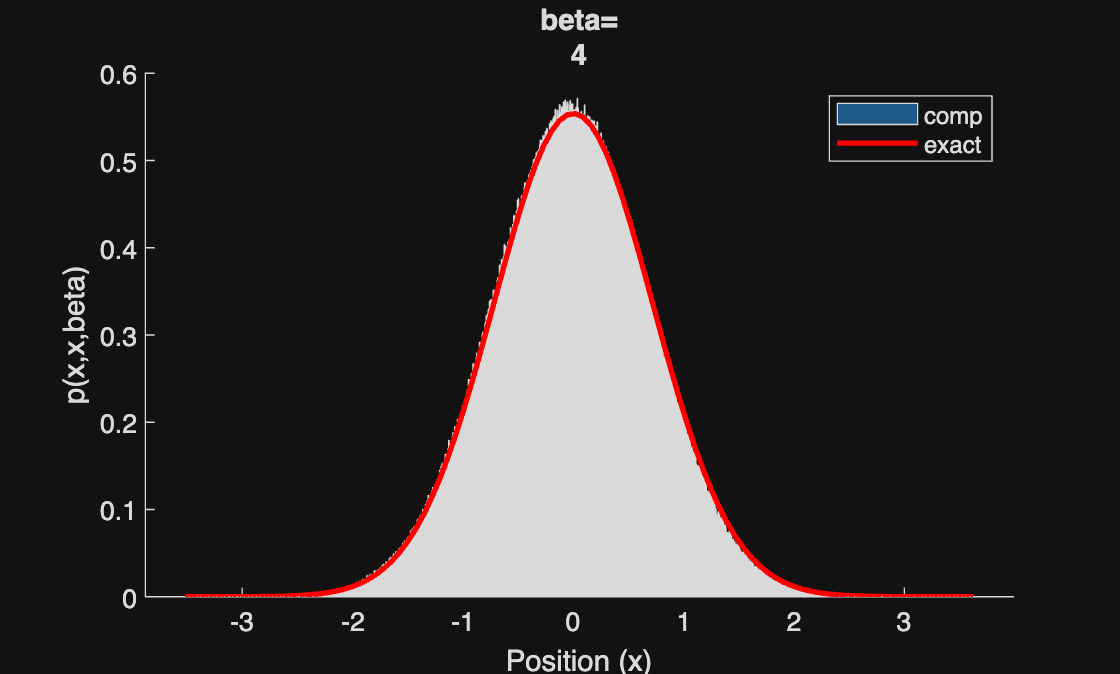

N=20;
xin=linspace(-1,1,N);
nsteps=10000000;
beta=4;
samples=nhp(xin,beta,0.5,nsteps);
burn=round(0.2*nsteps);
samples=samples(burn:nsteps,:);
samples=samples(:)';
xplot=linspace(min(samples),max(samples),100);
pexact=sqrt(tanh(beta/2)/pi)*exp(-xplot.^2*tanh(beta/2)); %diagonal density matrix of eq 6.24, normalized by dividing by Z(beta)
figure;
hold on;
histogram(samples,'Normalization','pdf');
plot(xplot,pexact,'r-','LineWidth',2);
xlabel('Position (x)');
ylabel('p(x,x,beta)');
legend('comp',"exact");
title(["beta=",num2str(beta)]);

We can see that the naive harmonic path algorithm recovers the analyitcal results of 6.24 at different tempuratures

function xout = nhp2(x,beta,delta,n) %Positions,beta,delta,#iterations
N=length(x);
xout=zeros(n,N);
dt=beta/N;
for i = 1:n
    k=randi(N);
    kplus=mod(k,N)+1; %adjusted for matlab indexing, ensuring if K = "N" K+ <- 1
    kminus=mod(k-2,N)+1; %adjusted for matlab indexing, ensuring if K = "0" K- <- "N-1"
    xdash=x(k)+(2*rand()-1)*delta;
    %prefactor of pfree cancels out when setting upsilon = pib/pia so have
    %removed from calculation, again setting m=h=1 for simplicity
    expa=(-(x(kminus)-x(k))^2 / (2*dt)) + (-(x(k)-x(kplus))^2 / (2*dt)) - dt*(0.5*x(k)^2+0.25*x(k)^4);
    expb=(-(x(kminus)-xdash)^2 / (2*dt)) + (-(xdash-x(kplus))^2 / (2*dt)) - dt*(0.5*xdash^2+0.25*xdash^4);
    upsilon=exp(expb-expa);
    if rand() < upsilon
        x(k) = xdash;
    end
    xout(i,:)=x;
end
end

function [xvec,p1diag]=matrixsquare2(L,N,beta,n) %Length,#postions,beta,#repititions
%for simplicity m=h=1
xvec=linspace(-L,L,N)';
dx=2*L/(N-1);
[x,xdash]=meshgrid(xvec,xvec);
%trotter approximate of p with V(x)=1/2 * x^2 + 1/4 * x^4
pfree=sqrt(1/(2*pi*beta))*exp(-(x-xdash).^2/(2*beta));
e1=exp(-0.5*beta*(0.5*x.^2+0.25*x.^4));
e2=exp(-0.5*beta*(0.5*xdash.^2+0.25*xdash.^4));
p1=e1.*pfree.*e2;
%incorperates both for loops of algorithm, repeats n times
for i = 1:n
    p1=dx*(p1*p1);
end
p1diag=diag(p1);
figure;
end

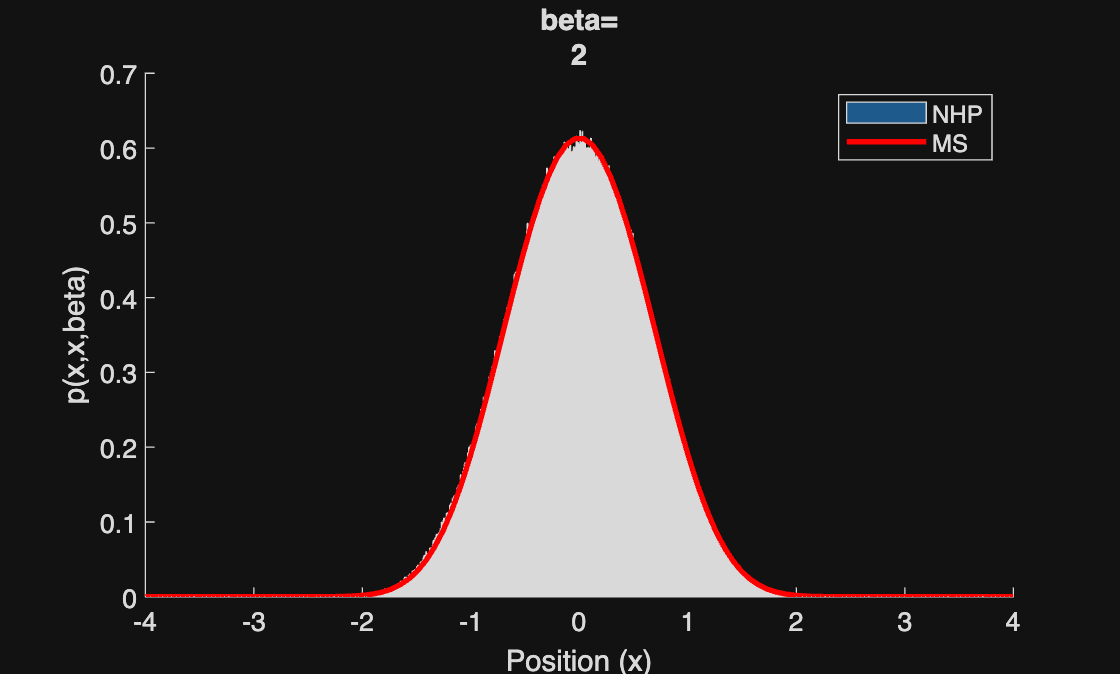

N=20;
xin=linspace(-1,1,N);
nsteps=10000000;
beta=2;
samples=nhp2(xin,beta,0.5,nsteps);
burn=round(0.2*nsteps);
samples=samples(burn:nsteps,:);
samples=samples(:)';
nreps=4;
%L=4 chosen to be approx 5 times sd of p so it encompases 99% of guassian
%like distribution
[xvec,pdiag]=matrixsquare2(4,100,beta/(2^nreps),nreps);
Z=trapz(xvec,pdiag);
pnorm=pdiag/Z;
figure;
hold on;
histogram(samples,'Normalization','pdf');
plot(xvec,pnorm,"r-",'LineWidth',2)
xlabel('Position (x)');
ylabel('p(x,x,beta)');
legend('NHP',"MS");
title(["beta=",num2str(beta)]);

We can see that the naive harmonic path algorithm recovers the same diagonal density matrix as the matrix squaring algorithm for an anharmonic oscillator